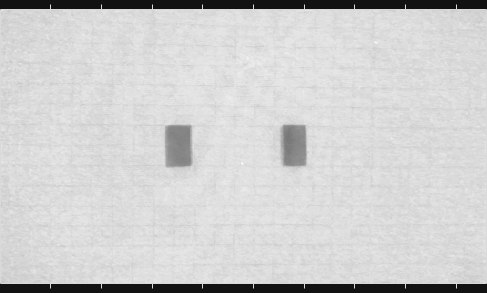

green = "green_cubes_Color.png";

[I_g, g_map] = imread(green); % TODO: Adaptive hist equalization
[rg,gg,bg] = imsplit(I_g);
imgLab = rgb2lab(I_g);
[L,a,b] = imsplit(imgLab);
imshow(a,[])

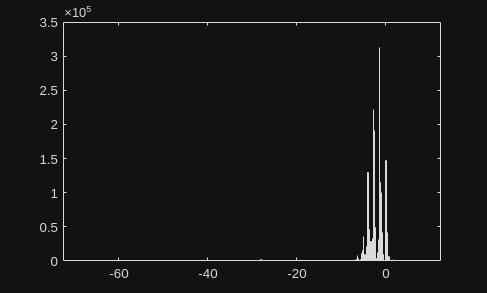

histogram(a)

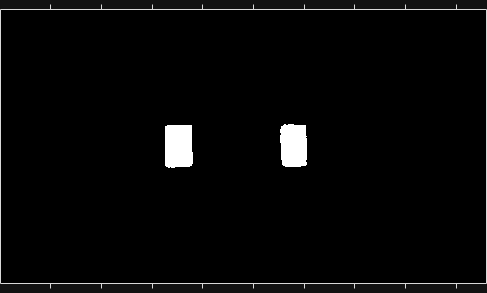


masked = a < -10;
imshow(masked);

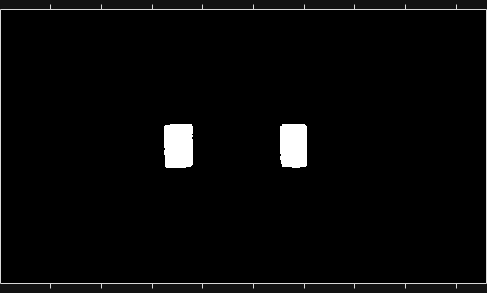

masked_med = wiener2(masked, [5,5]);
mask1 = bwareaopen(masked_med, 2000);
mask2 = imclearborder(mask1);
imshow(mask2)


% gmask = imbinarize(g)
% imshow(gmask)